# Polinomis en Matlab

#### EXEMPLE:

% Polinomi x^3 + 3x^2 - 3x + 1

p = [1 3 -3 1];

x = linspace(-5,5,50);
y = polyval(p,x);

plot(x,y); roots(p)

ans =       -3.8473 +          0i
      0.42366 +    0.28361i
      0.42366 -    0.28361i


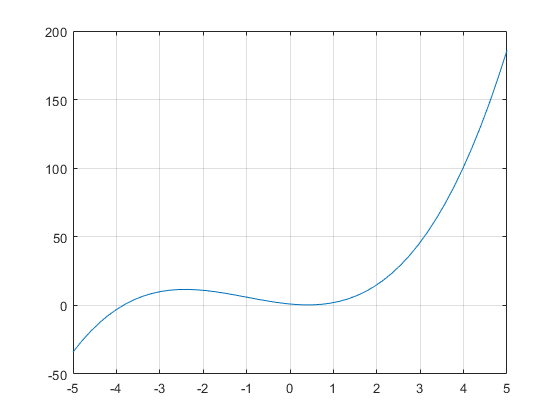

grid;

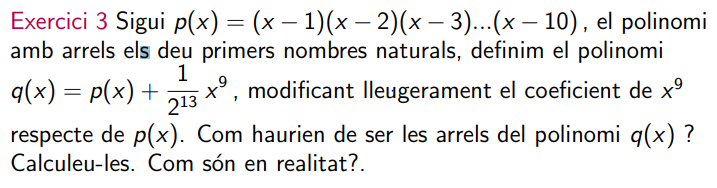

clear vars;

r = 1:10;
p = poly(r); p'

ans =            1
         -55
        1320
      -18150
      157773
     -902055
     3416930
    -8409500
    12753576
   -10628640



q = p; q(2) = q(2) + 1/2^23

q =             1          -55         1320       -18150   1.5777e+05  -9.0206e+05   3.4169e+06  -8.4095e+06   1.2754e+07  -1.0629e+07   3.6288e+06


q'

ans =             1
          -55
         1320
       -18150
   1.5777e+05
  -9.0206e+05
   3.4169e+06
  -8.4095e+06
   1.2754e+07
  -1.0629e+07


roots(q)

ans =        9.9997
       9.0011
       7.9984
       7.0011
       5.9996
       5.0001
            4
            3
            2
            1


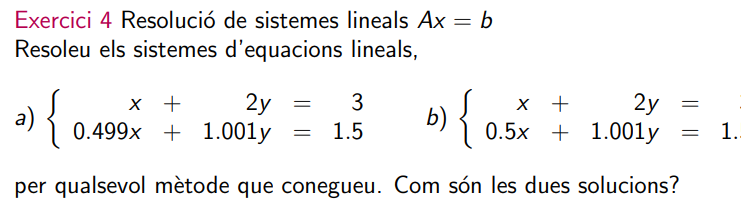 

A = [1, 2; 0.499, 1.001];
s = [3; 1.5];
sol1 = A\s

sol1 =             1
            1



B = [1, 2; 0.5, 1.001];
s = [3; 1.5];
sol2 = B\s

sol2 =      3
     0



array2table([[sol1,sol2, ]', [det(A);det(B)]], 'VariableNames', {'x', 'y', 'Det'}, 'RowNames', {'A', 'B'})

ans = 2×3 table
         x    y     Det 
         _    _    _____

    A    1    1    0.003
    B    3    0    0.001


ans =        2083.7
